Marion Gilson, 30/01/2022

Cours Apprentissage de systèmes dynamiques, 4A IA2R apprentissage.

Ce TD vous permet d'apprendre les différentes étapes nécessaires à l'identification d'un système à partir de données réelles mesurées. On utilisera pour ce faire les données de dryer2 de Matlab. Toutes les étapes peuvent être utilisées ensuite avec d'autres données mesurées.

## I. Données

On commence par séparer les données qui vont nous servir à l'estimation et celles utilisées pour la validation des modèles (validation dite croisée).

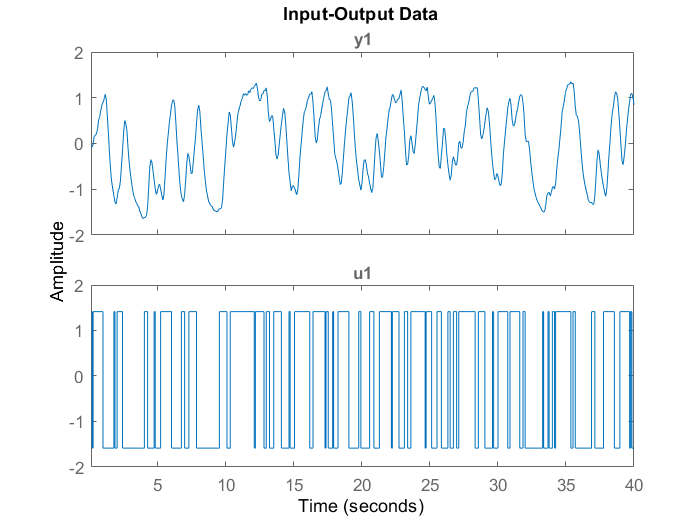

clear
close all

load dryer2
Ts=0.08;
data=iddata(y2(1:500),u2(1:500),Ts); % pour l'estimation
dataV=iddata(y2(501:end),u2(501:end),Ts); %pour validation

% Prétraitement des données (on enlève la moyenne, ici pas de dérive)
data=detrend(data,0);
dataV=detrend(dataV,0);
idplot(data)

## II. Estimations initiales

Avant de se lancer dans une estimation d'un modèle de type boîte noire, il faut acquérir des connaissances sur le système. Plusieurs étapes sont nécessaires.

### II.1 Estimation de la réponse fréquentielle

La réponse fréquentielle et la réponse impulsionnelle sont des modèles non paramétriques qui permettent d'aider à la compréhension des principales caractéristiques du système à identifier. Ces modèles ne sont pas représentés par une formule mathématique, mais plutôt à l'aide de représentation graphique.

La toolbox System Identification de Matlab comporte 3 fonctions pour estimer la réponse fréquentielle :

- etfe calcule la fonction de transfert empirique en utilisant l'analyse de Fourier ;

- spa estime la fonction de transfert à partir de l'analyse spectrale, pour une résolution de fréquence fixée ;

- spafdr permet de choisir la fréquence de résolution d'intérêt pour estimer la réponse fréquentielle.

On propose ici d'utilise la fonction spa.

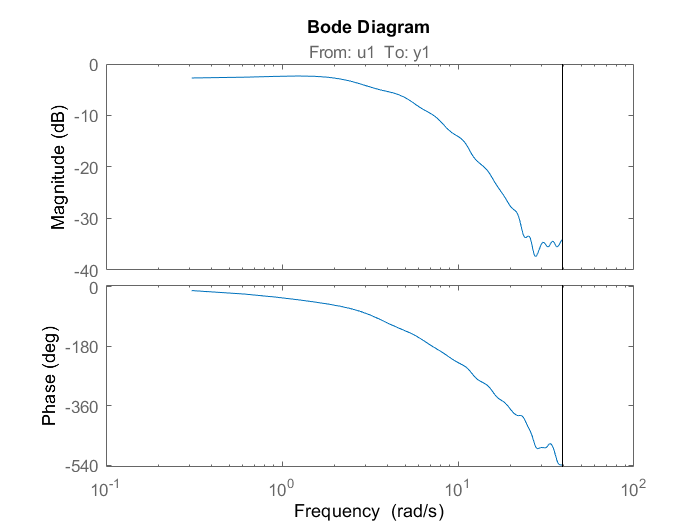

Ge=spa(data);
%Représentation de la réponse fréquentielle par un diagramme de Bode
bode(Ge)

On remarque ici qu'il n'y a pas de pic de résonnance et que la descente a une pente qui se situe entre -20 et -40dB/decade.

On voit également que la phase descend rapidement, ce qui peut peut-être suggérer un retard entre la sortie et l'entrée.

### II.2 Estimation de la réponse indicielle empirique

Pour estimer la réponse indicielle à partir des données, il faut tout d'abord estimer un modèle FIR (Finite Impulse Response) à partir des données puis représenter sur une figure sa réponse indicielle.

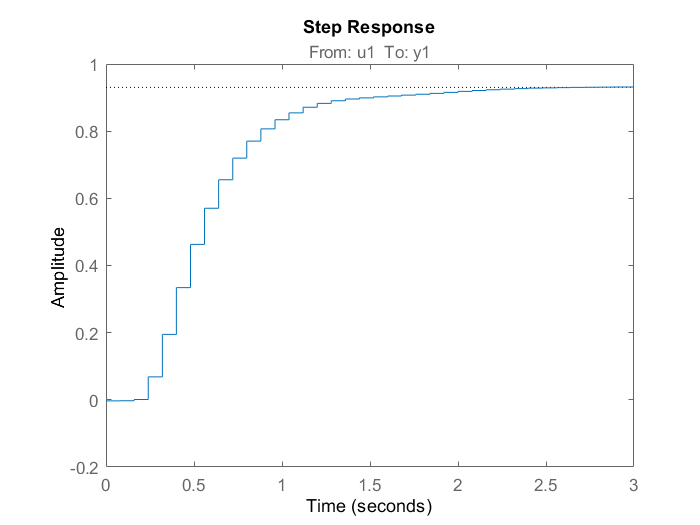

% Estimation du modèle
Mimp=impulseest(data,60);

%réponse indicielle
step(Mimp)

On remarque qu'il n'y a pas de dépassement, ce qui indique qu'il s'agit soit d'un système du 1er ordre, soit d'un système d'ordre supérieur mais à pôles réels.

On note aussi un retard sur le système, ce qui confirme la descente rapide sur la phase du Bode. Il nous faut donc estimer ce retard.

### II.3 Estimation du retard

Il est important d'avoir une estimation du retard pour pouvoir utiliser cette connaissance ensuite lors de l'estimation de modèle boîte noire de type arx, ou autre.

Cette valeur peut être directement lue sur la réponse indicielle ou (mieux) estimée grâce à la commande delayest.

delayest(data)

ans = 3

Le retard estimé est donc de 3 échantillons. Vérifions cette estimation en utilisant la réponse impulsionnelle estimée, puis représentons à l'écran l'intervalle de confinace accordée à cette estimation.

clf
h = impulseplot(Mimp);
showConfidence(h,3)


### II.4 Estimation de la structure du modèle

Pour pouvoir estimer un modèle boîte noire (arx, oe ou autre), il est nécessaire de connaitre l'odre des polynômes de la fonction de transfer. Comme ils sont inconnus, nous allons, dans cette partie, utiliser 3 fonctions de Matlab pour estimer les ordres d'un modèle ARX : 

- struc crée une matrice avec les ordres de modèles sélectionnés dans un ordre spécifique : na, nb, nk ;

- arxstruc estime pour chaque ordre de modèle de struc le modèle arx correspondant et effectue une comparaison entre la sortie mesurée et la sortie issue de chaque modèle ; il retourne ensuite une fonction coût pour chaque modèle qui correspond à la somme normalisée des erreurs de prédiction au carré ;

- selstruc utilise la sortie de arxstruc et ouvre une fenêtre de sélection de modèle pour chacun. Il faut alors utiliser cette fenêtre pour sélectionner le modèle approprié. 3 critères sont proposés : best fit, critère Rissanen, critère Akaike.

D'après les études précédentes, il parait intéressant de tester les ordres suivants :

- na=1:4 ;

- nb=1:4 ;

- nk=3.

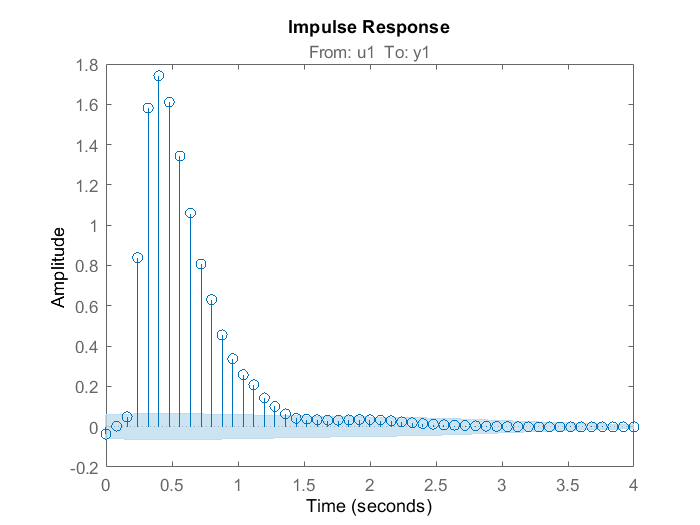

ans =      2     2     3


NN=struc(1:4,1:4,1:4);
selstruc(arxstruc(data,dataV,NN))

D'après la figure provenant de selstruc, plusieurs structures de modèle donnent quasiment le même résultat qui est : na=4, nb=4, nk=3 ou na=2, nb=2, nk=3. D'après les études précédentes, il semble que l'ordre 2 soit suffisant. De plus il est otujrous préférable de choisri le modèle le plus parcimonieux.

### II.5 Estimation d'une fonction de transfert

Cette étape est facultative.

#### Estimation

Avec les dernières versions de Matlab, on peut désormais estimer une fonctoin de trasnfert à temps continu directement à partir des données. Il faut d'abord avoir préparé les données (cf plus haut) et connaître l'ordre de la FT. On utilise pour ce faire la fonction tfest.

% pour voir un rapport de progression, on utilise l'option Display
Opt=tfestOptions('Display','off');

% on collecte les ordres du modèles
np=2;
ioDelay=3*Ts; % 3 échantillons en s

%estimation de la FT
mtf=tfest(data,np,[],ioDelay,Opt);
  
%pour voir les coefficients du modèle
mtf

mtf =
 
  From input "u1" to output "y1":
                    2.628 s + 0.3385
  exp(-0.24*s) * ----------------------
                 s^2 + 2.966 s + 0.3636
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 84.69%                   
FPE: 0.01683, MSE: 0.01643                       


Le modèle donne un fit de quasi 85%, ce qui parait une bonne estimation. Ces résultats doivent tout de même être confirmés par une étape de validation du modèle.

#### Validation du modèle FT

On peut comparer la sortie du modèle avec la sortie mesurée à l'aide de la fonction compare.

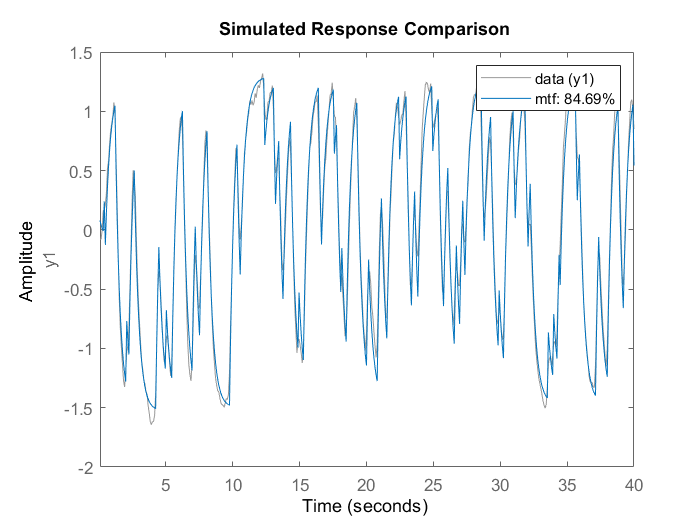

compare(data,mtf)

La comparaison montre un fit d'environ 85%. On peut ensuite analyser les résidus, à l'aide de la commande resid.

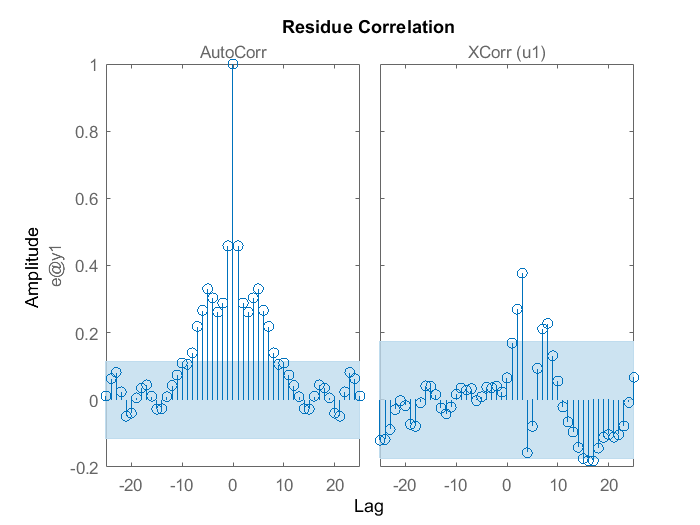

resid(data,mtf)

Les résidus montrent un haut degré d'autocorrélation, ce qui signifie que le modèle n'est pas de très bonne qualité (il reste trop d'information dans les résidus). Ceci est logique car nous n'avons pas séparé l'estimation du process de celle du bruit.

Pour ce faire, il faut utiliser les fonctions du type arx, oe, bj, iv, sriv...

## III. Estimation d'un modèle boîte noire

Nous avons appris à utiliser les fonction arx, iv4, oe, sriv pour estimer un modèle boîte noire de notre process. Nous allons les utiliser ici.

### Estimation d'un modèle arx par moindres carrés et iv4

nnarx=[3 3 3];
marx=arx(data,nnarx);
miv4=iv4(data,nnarx);
present(marx)

                                                                                               
marx =                                                                                         
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                            
  A(z) = 1 - 0.9895 (+/- 0.04295) z^-1 + 0.03428 (+/- 0.05695) z^-2 + 0.1129 (+/- 0.02205) z^-3
                                                                                               
  B(z) = 0.06634 (+/- 0.001543) z^-3 + 0.06056 (+/- 0.003281) z^-4 + 0.01803 (+/- 0.00306) z^-5
                                                                                               
Sample time: 0.08 seconds                                                                      
                                                                                               
Parameterization:                                                                              
   Polynomial orders:   na=3   nb=3   nk

present(miv4)

                                                                                             
miv4 =                                                                                       
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                          
  A(z) = 1 - 1.727 (+/- 0.3776) z^-1 + 1.002 (+/- 0.4921) z^-2 - 0.2025 (+/- 0.1597) z^-3    
                                                                                             
  B(z) = 0.06711 (+/- 0.001503) z^-3 + 0.01049 (+/- 0.02381) z^-4 - 0.01136 (+/- 0.0171) z^-5
                                                                                             
Sample time: 0.08 seconds                                                                    
                                                                                             
Parameterization:                                                                            
   Polynomial orders:   na=3   nb=3   nk=3                  

Estimation d'un modèle oe par oe et sriv

nnoe=[3 3 3];
moe=oe(data,nnoe);
msriv=sriv(data,nnoe);

Unrecognized function or variable 'sriv'.

present(moe)
present(msriv)


## IV. Comparaison des différentes méthodes d'estimation

compare(dataV,marx,miv4,moe,msriv)

Toutes les méthodes donnent de bons résultats, avec un légère préférence pour oe et sriv. Analysons les résidus.

resid(dataV,marx,miv4,moe,msriv)

Bien que l'estimation semblait de bonne qualité, il reste encore des informations dans les résidus (autocorrélation trop importante). Une solution peut être trouvée en estimant un modèle de bruit différent, et plus particulièrement en estimant un modèle de type Box-Jenkins :

y=B/Fu+C/De

Comme nous n'avons pas d'information particulière sur le modèle de bruit, on prend simplement un modèle d'ordre 1 pour la fonction de transfert du bruit (pour C comme pour D).

nnbj=[2 1 1 2 3];
mbj=bj(data,nnbj);
compare(dataV,mbj)
resid(dataV,mbj)

L'estimation semble désormais de très bonne qualité. On comprend ainsi l'intérêt d'estimer un modèle de bruit.


h = iopzplot(mbj);
showConfidence(h,3)